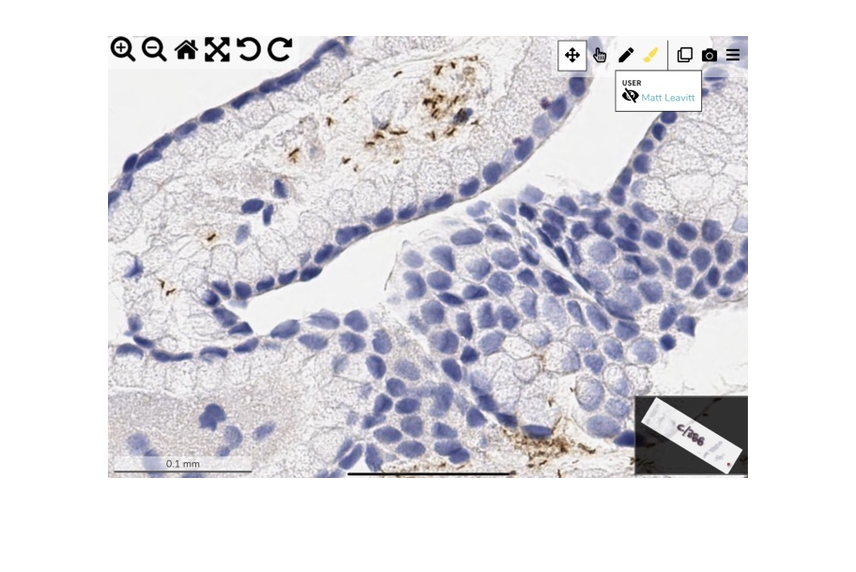

addpath('/Users/karthikdharmarajan/Downloads/H.pylori/branches/Karthik/Negative Examples/')
addpath('/Users/karthikdharmarajan/Downloads/H.pylori/branches/Karthik/Positive Examples/')

MasterImage = imread('MasterImage','jpeg');
AnnotatedMasterImage = imread('AnnotatedMasterImage.jpeg');

imshow(MasterImage)

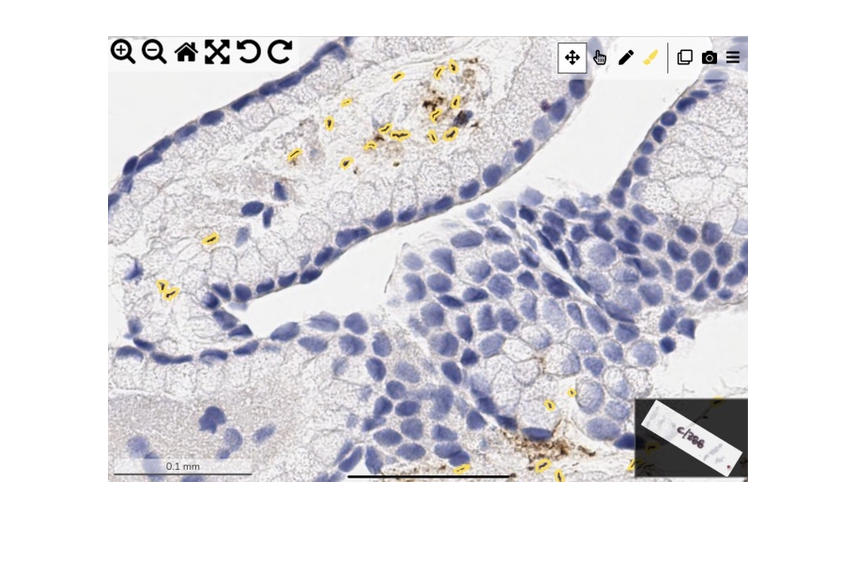

imshow(AnnotatedMasterImage)

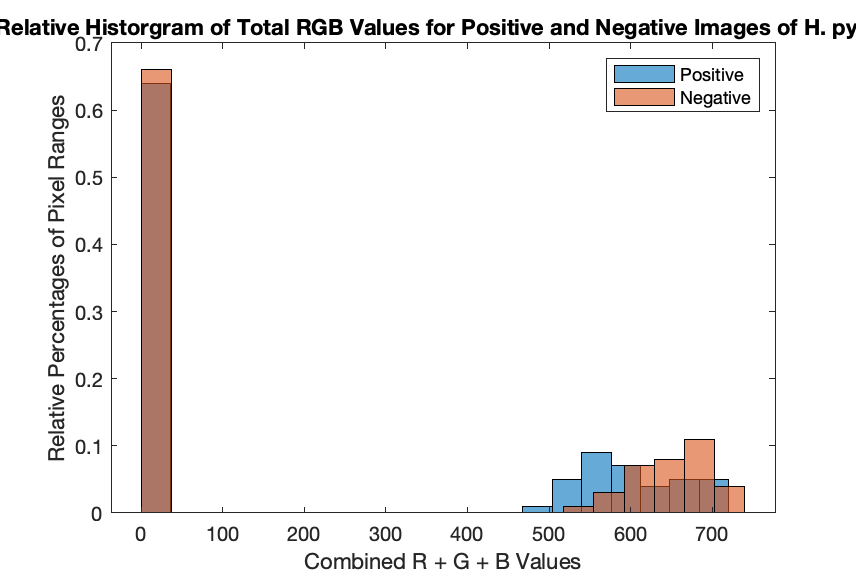


ExamplePositive = imread('ExamplePositive.jpeg');
ExampleNegative = imread('ExampleNegative.jpeg');

[rEP,cEP] = size(ExamplePositive);
[rEN,cEN] = size(ExampleNegative);

totalRGBValue = [];

for i = 1:rEP
    for j = 1:cEP
        temp = sum(impixel(ExamplePositive,i,j));
        if(temp > 500)
            totalRGBValue(i * j) = temp;
        end
    end
end


totalRGBValue2 = [];

for i = 1:rEN
    for j = 1:cEN
        temp = sum(impixel(ExampleNegative,i,j));
        if(temp > 500)
            totalRGBValue2(i * j) = temp;
        end
    end
end

distributionRGB = histogram(totalRGBValue,20,'Normalization','probability');

hold on

distributionRGB2 = histogram(totalRGBValue2,20,'Normalization','probability');

title("Relative Historgram of Total RGB Values for Positive and Negative Images of H. pylori");
xlabel("Combined R + G + B Values");
ylabel("Relative Percentages of Pixel Ranges");
legend("Positive",'Negative');
hold off

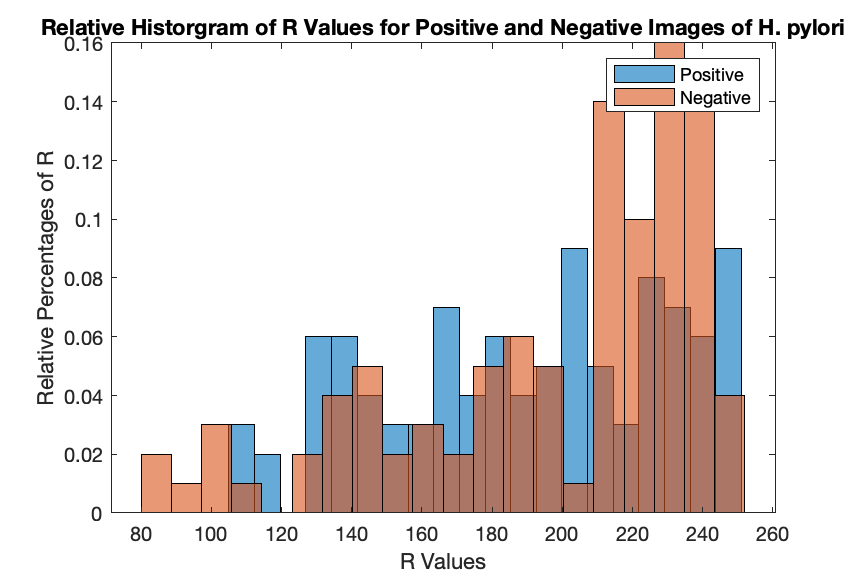


distributionR = histogram(ExamplePositive(:,:,1),20,'Normalization','probability');

hold on

distributionR2 = histogram(ExampleNegative(:,:,1),20,'Normalization','probability');

title("Relative Historgram of R Values for Positive and Negative Images of H. pylori");
xlabel("R Values");
ylabel("Relative Percentages of R");
legend("Positive",'Negative');
hold off

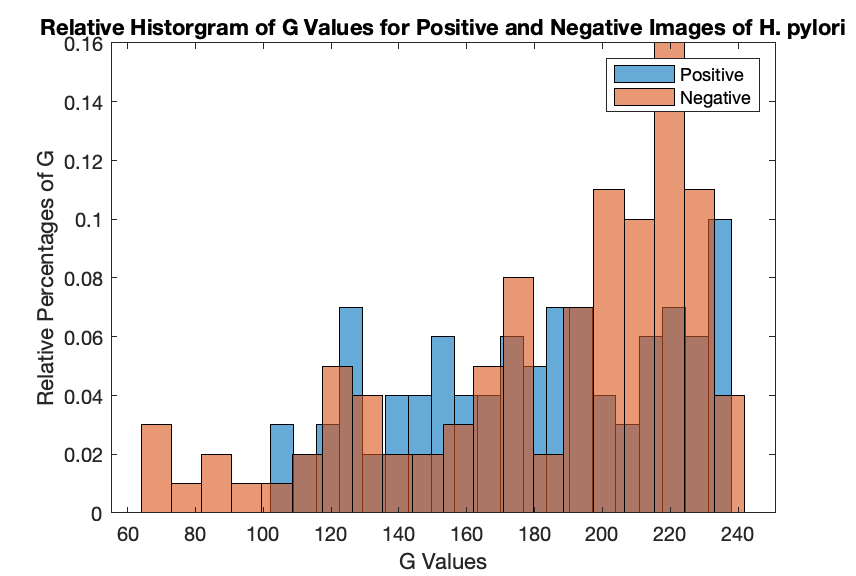


distributionG = histogram(ExamplePositive(:,:,2),20,'Normalization','probability');

hold on

distributionG2 = histogram(ExampleNegative(:,:,2),20,'Normalization','probability');

title("Relative Historgram of G Values for Positive and Negative Images of H. pylori");
xlabel("G Values");
ylabel("Relative Percentages of G");
legend("Positive",'Negative');
hold off

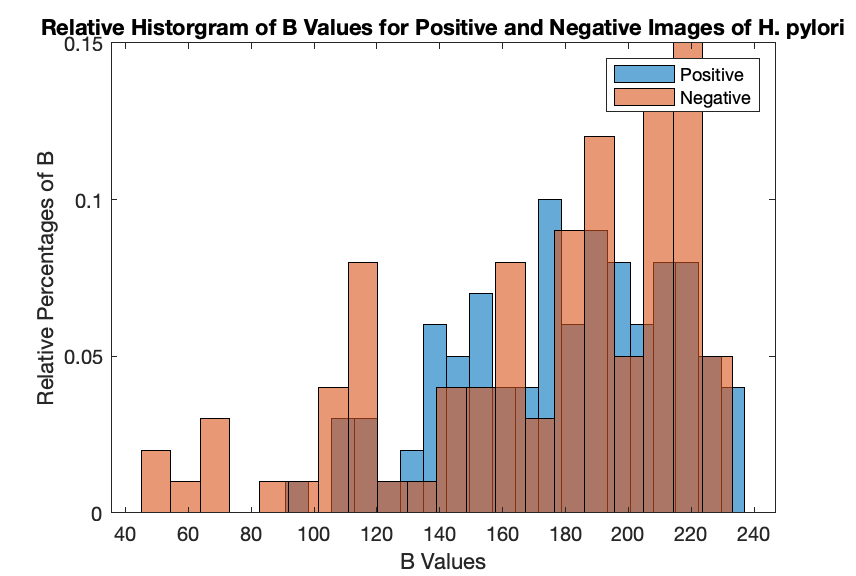


distributionB = histogram(ExamplePositive(:,:,3),20,'Normalization','probability');

hold on

distributionB2 = histogram(ExampleNegative(:,:,3),20,'Normalization','probability');
title("Relative Historgram of B Values for Positive and Negative Images of H. pylori");
xlabel("B Values");
ylabel("Relative Percentages of B");
legend("Positive",'Negative');

ExamplePositive2 = imread('ExamplePositive2.jpeg');
ExampleNegative2 = imread('ExampleNegative2.jpeg');

hold off

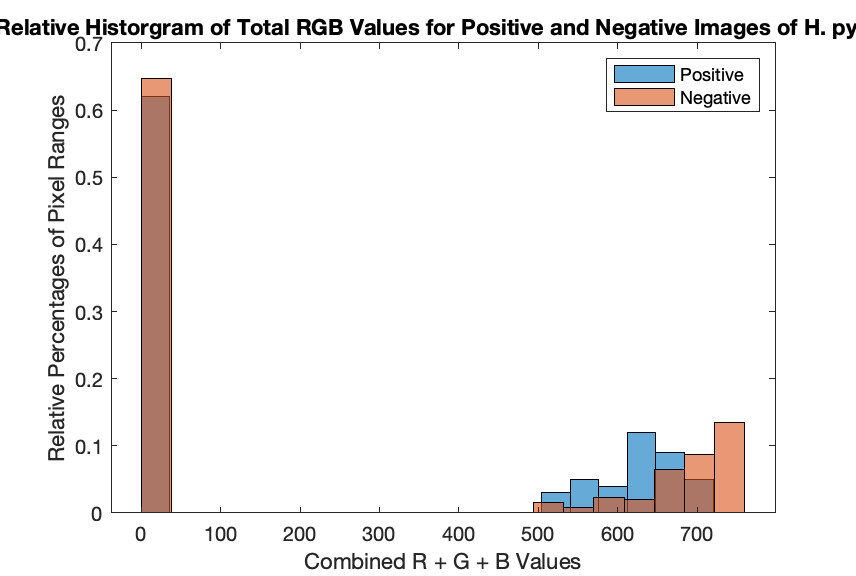


[rEP2,cEP2] = size(ExamplePositive2);
[rEN2,cEN2] = size(ExampleNegative2);

totalRGBValue = [];

for i = 1:rEP2
    for j = 1:cEP2
        temp = sum(impixel(ExamplePositive2,i,j));
        if(temp > 500)
            totalRGBValue(i * j) = temp;
        end
    end
end


totalRGBValue2 = [];

for i = 1:rEN2
    for j = 1:cEN2
        temp = sum(impixel(ExampleNegative2,i,j));
        if(temp > 500)
            totalRGBValue2(i * j) = temp;
        end
    end
end

distributionRGB3 = histogram(totalRGBValue,20,'Normalization','probability');

hold on

distributionRGB4 = histogram(totalRGBValue2,20,'Normalization','probability');

title("Relative Historgram of Total RGB Values for Positive and Negative Images of H. pylori");
xlabel("Combined R + G + B Values");
ylabel("Relative Percentages of Pixel Ranges");
legend("Positive",'Negative');
hold off

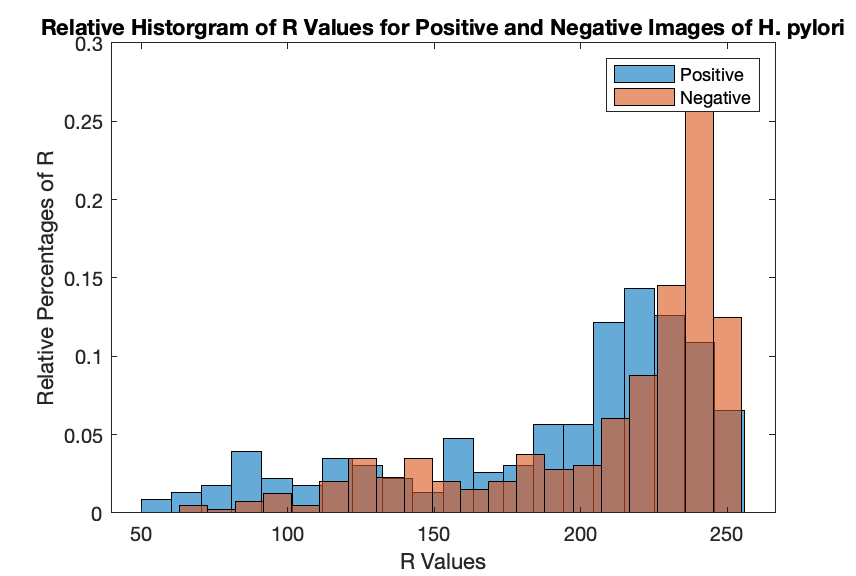


distributionR = histogram(ExamplePositive2(:,:,1),20,'Normalization','probability');

hold on

distributionR2 = histogram(ExampleNegative2(:,:,1),20,'Normalization','probability');

title("Relative Historgram of R Values for Positive and Negative Images of H. pylori");
xlabel("R Values");
ylabel("Relative Percentages of R");
legend("Positive",'Negative');
hold off

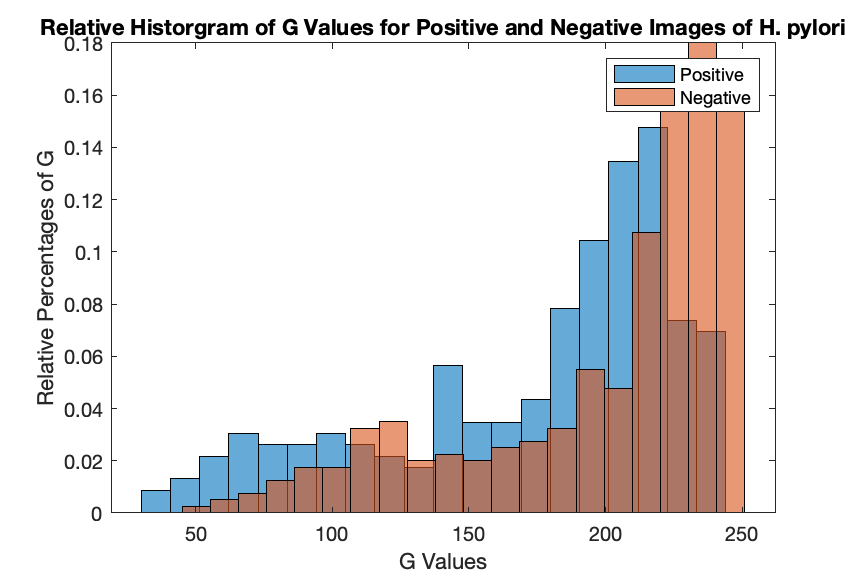


distributionG = histogram(ExamplePositive2(:,:,2),20,'Normalization','probability');

hold on

distributionG2 = histogram(ExampleNegative2(:,:,2),20,'Normalization','probability');

title("Relative Historgram of G Values for Positive and Negative Images of H. pylori");
xlabel("G Values");
ylabel("Relative Percentages of G");
legend("Positive",'Negative');
hold off

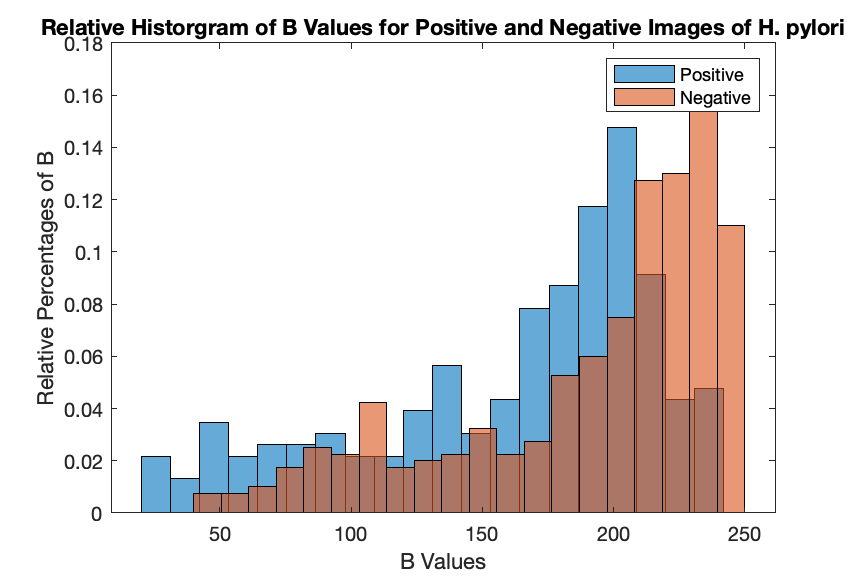


distributionB = histogram(ExamplePositive2(:,:,3),20,'Normalization','probability');

hold on

distributionB2 = histogram(ExampleNegative2(:,:,3),20,'Normalization','probability');
title("Relative Historgram of B Values for Positive and Negative Images of H. pylori");
xlabel("B Values");
ylabel("Relative Percentages of B");
legend("Positive",'Negative');